%pan-tompkinson algorithm

[tm,signal,Fs,labels]=rdmat('100m');

tm

tm =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


signal

signal =    -0.1450   -0.0650
   -0.1450   -0.0650
   -0.1450   -0.0650
   -0.1450   -0.0650
   -0.1450   -0.0650
   -0.1450   -0.0650
   -0.1450   -0.0650
   -0.1450   -0.0650
   -0.1200   -0.0800
   -0.1350   -0.0800


ch1=signal(:,1)

ch1 =    -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1200
   -0.1350


ch2=signal(:,2)

ch2 =    -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0800
   -0.0800



t=tm(1:1800)

t =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


s1=ch1(1:1800)

s1 =    -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1450
   -0.1200
   -0.1350


s2=ch2(1:1800)

s2 =    -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0650
   -0.0800
   -0.0800


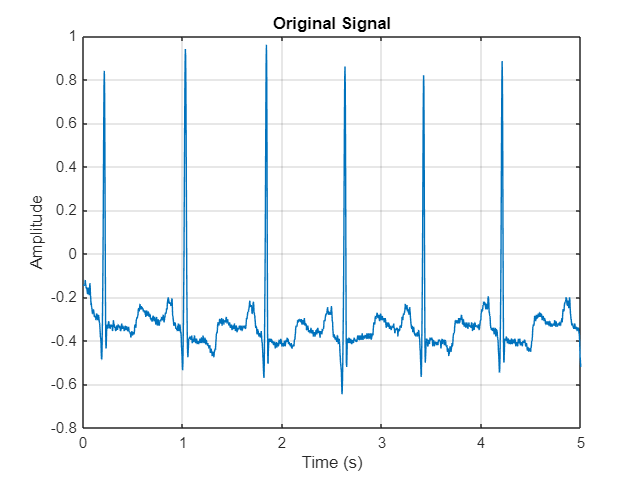


function y = low_pass_filter_hw(x)
    % Define fixed-point properties
    T = numerictype(1, 16, 8); % Signed, 16-bit, 8 fractional bits
    F = fimath('OverflowAction', 'Wrap', 'RoundingMethod', 'Floor');
    
    % Convert input to fixed-point
    x = fi(x, T, F); % Fixed-point input
    N = length(x); % Length of the input sequence
    
    % Initialize output as fixed-point
    y = fi(zeros(size(x)), T, F); % Fixed-point output

    % Process the filter equation
    for n = 13:N
        y(n) = 2 * y(n-1) - y(n-2) + x(n) - 2 * x(n-6) + x(n-12);
    end
end

% Initialize variables
x = s1; % Input signal
N = length(x); % Length of the input signal
y1 = zeros(1, N); % Initialize the output signal y(n)

y1 = low_pass_filter_hw(x);

% Plot the original and filtered signals

plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');
grid on;

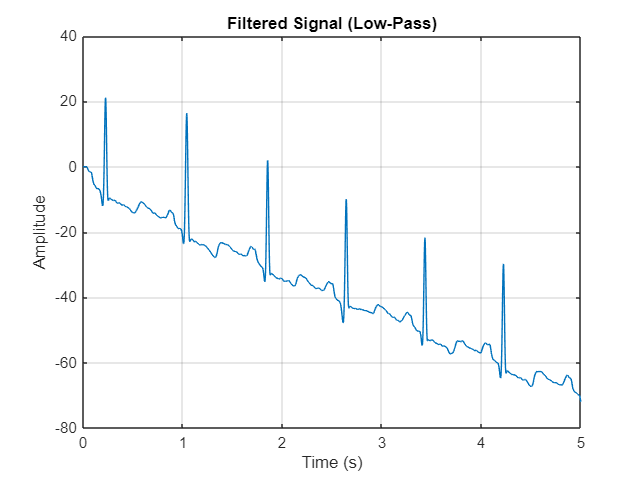


plot(t, y1);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Low-Pass)');
grid on;

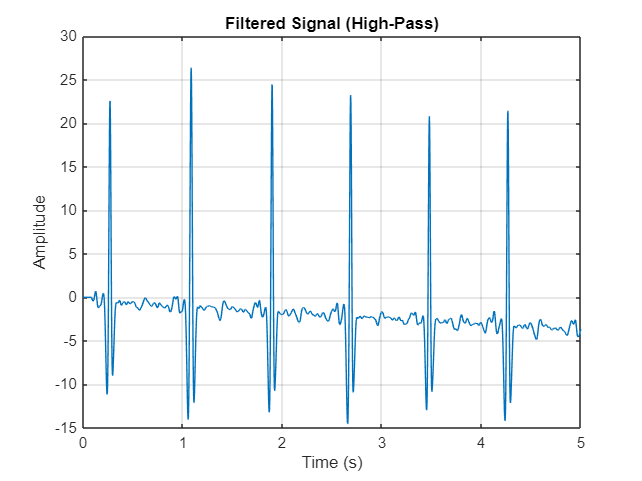


function y = high_pass_filter_hw(x)
    % Define fixed-point properties
    T = numerictype(1, 16, 8); % Signed, 16-bit, 8 fractional bits
    F = fimath('OverflowAction', 'Wrap', 'RoundingMethod', 'Floor');
    
    % Convert input to fixed-point
    x = fi(x, T, F); % Fixed-point input
    N = length(x); % Length of the input sequence

    % Initialize output as fixed-point
    y = fi(zeros(size(x)), T, F); % Fixed-point output

    % Process the filter equation
    for n = 33:N
        y(n) = y(n-1) - (1/32) * x(n) + x(n-16) - x(n-17) + (1/32) * x(n-32);
    end
end

y2 = high_pass_filter_hw(y1);

plot(t, y2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (High-Pass)');
grid on;

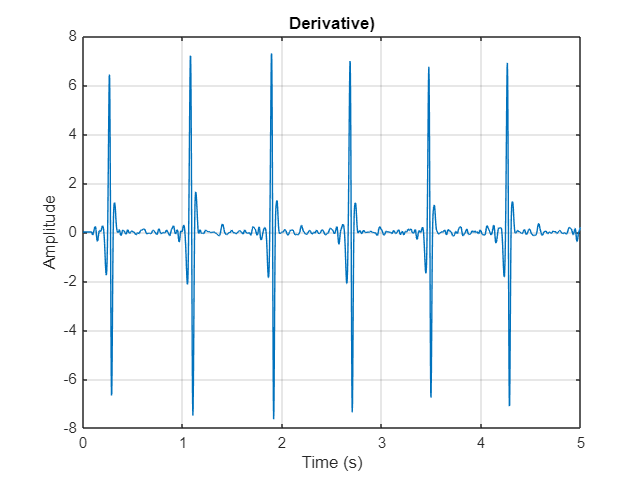


function y = derivative_hw(x)
    % DERIVATIVE_FILTER_HW - Implements a derivative filter using
    % the formula:
    % y(n) = (1/8) * (2*x(n) + x(n-1) - x(n-3) - 2*x(n-4))
    
    % Initialize variables
    N = length(x);
    y = zeros(1, N); % Output signal

    % Apply the filter
    for n = 5:N  % Start at n=5 because of the x(n-4) term
        y(n) = (1/8) * (2*x(n) + x(n-1) - x(n-3) - 2*x(n-4));
    end
end

y3 = derivative_hw(y2);

plot(t, y3);
xlabel('Time (s)');
ylabel('Amplitude');
title('Derivative)');
grid on;

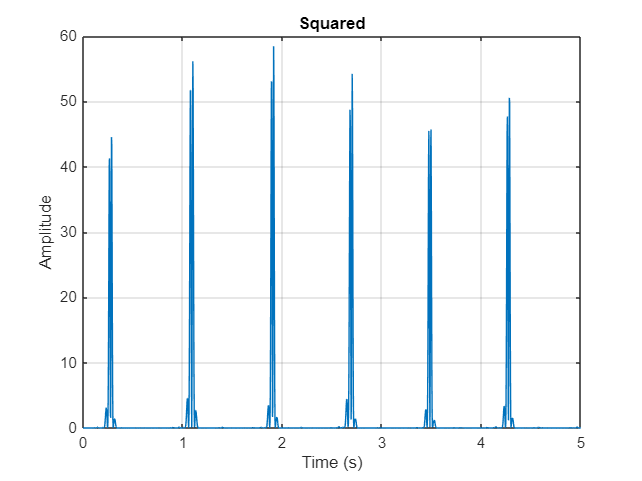


function y = square_hw(x)
    % SQUARE_FILTER_HW - Implements a hardware-compatible squaring filter.
    % Formula: y(n) = x(n)^2
    
    % Initialize variables
    N = length(x);
    y = zeros(1, N); % Output signal

    % Apply the squaring filter
    for n = 1:N
        y(n) = x(n)^2; % Square each sample
    end
end

y4 = square_hw(y3);

plot(t, y4);
xlabel('Time (s)');
ylabel('Amplitude');
title('Squared');
grid on;

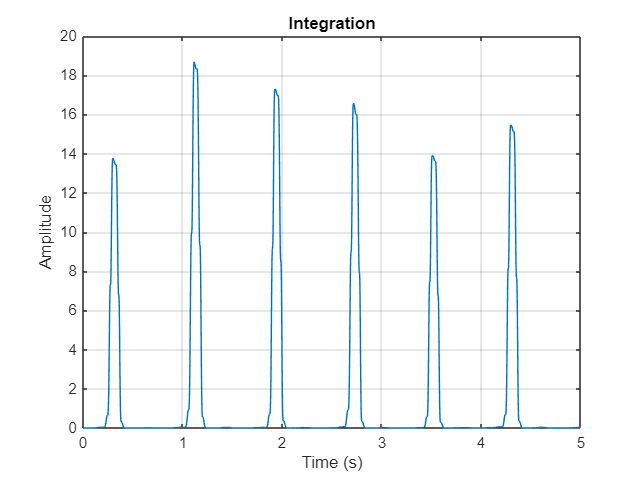


function y = integration_hw(x)
    % INTEGRATION_FILTER_HW - Implements a hardware-compatible integration filter.
    % Formula: y(n) = (1/30) * sum(x(n-29), ..., x(n))
    
    % Initialize variables
    N = length(x);
    y = zeros(1, N); % Output signal
    
    % Define the window size (30 samples as per the equation)
    window_size = 30;
    
    % Apply the integration filter
    for n = window_size:N
        % Sum the last 30 samples and divide by 30 to get the average
        y(n) = sum(x(n - window_size + 1:n)) / window_size;
    end
    
    % For the first few samples (less than 30), the filter cannot apply fully,
    % so we just set the output to zero or apply a different method if needed.
    y(1:window_size-1) = 0; % Set initial outputs to 0, or handle differently if required
end

y5 = integration_hw(y4);

plot(t, y5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Integration');
grid on;